## Objective: To verify the handwritten linearization of the magnetic levitator and evaluate the open-loop stability. 

The nonlinear force equation is:  $F(x,i) = \frac{ki^2}{x^2}$. 

syms x i x0 i0 k m g real % symbolic variables
F = (k * i^2) / x^2

$$F = \frac{i^{2}\,k}{x^{2}}$$

% partial derivatives
dF_dx = diff(F, x);
dF_di = diff(F, i);
% evaluate/linearize at equilibrium (x0, i0)
dF_dx_eq = subs(dF_dx, [x, i], [x0, i0]);
dF_di_eq = subs(dF_di, [x, i], [x0, i0]);

a_sym = -dF_dx_eq / m;
b_sym = dF_di_eq / m;
disp("jacobian");

jacobian


disp("a:"); disp(a_sym);

a:


$$\frac{2\,{i_{0}}^{2}\,k}{m\,{x_{0}}^{3}}$$

disp("b:"); disp(b_sym);

b:


$$\frac{2\,i_{0}\,k}{m\,{x_{0}}^{2}}$$

We can also use another method, which is the multivariable Taylor series:

% Expand F(x,i) around [x0, i0] up to first order terms
F_taylor = taylor(F, [x, i], [x0, i0], 'Order', 2);
disp('taylor');

taylor


disp(F_taylor);

$$\frac{{i_{0}}^{2}\,k}{{x_{0}}^{2}}-\frac{2\,{i_{0}}^{2}\,k\,\left(x-x_{0}\right)}{{x_{0}}^{3}}+\frac{2\,i_{0}\,k\,\left(i-i_{0}\right)}{{x_{0}}^{2}}$$

Now we can substitute the estimated constant to generate the transfer function:

$G(s) = \frac{-b}{s^2-a}$.

%constants
m_val = 0.01;
g_val = 9.81;
x0_val = 0.015;
i0_val = 0.5;
%derive k using mg = (k*i0^2)/x0^2
k_val = (m_val * g_val * x0_val^2) / (i0_val^2);
% find a and b, but numeric. 
a_num = double(subs(a_sym, [k,m,x0,i0], [k_val,m_val,x0_val,i0_val]));
b_num = double(subs(b_sym, [k,m,x0,i0], [k_val,m_val,x0_val,i0_val]));

%build transfer function
num = [-b_num];
den = [1, 0, -a_num];
sys = tf(num, den);
sys


sys =
 
    -39.24
  ----------
  s^2 - 1308
 
Continuous-time transfer function.


Now we can plot the pole-zero map to see the pole locations and if there is unstable pole

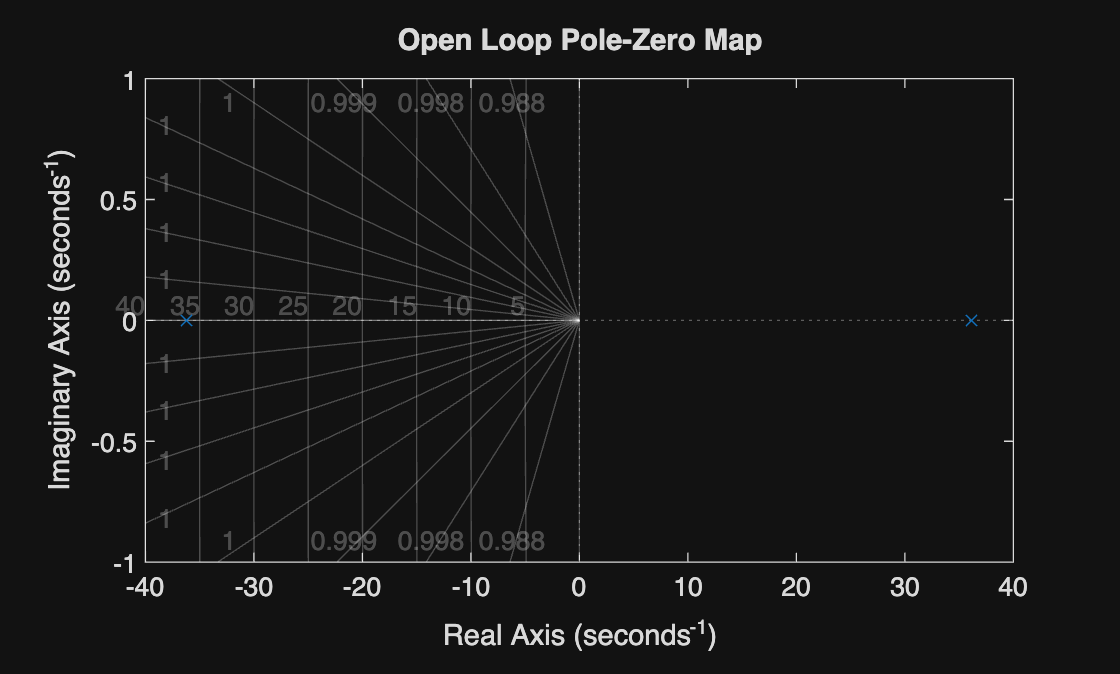

figure;
pzmap(sys);
title("Open Loop Pole-Zero Map");
grid on;

[p,z]=pzmap(sys);
disp(p);

  -36.1663
   36.1663



The pole is at 36.2 which matches our prediction of the pole being at $\sqrt{a}$.